# Imedance Matching and Maximum Power Point Tracking (MPPT)

Copyright © 2022 - 2024, The MathWorks, Inc.

## Impedance Matching

Maximum power is delivered to a load when the load impedance matches the source impedance.

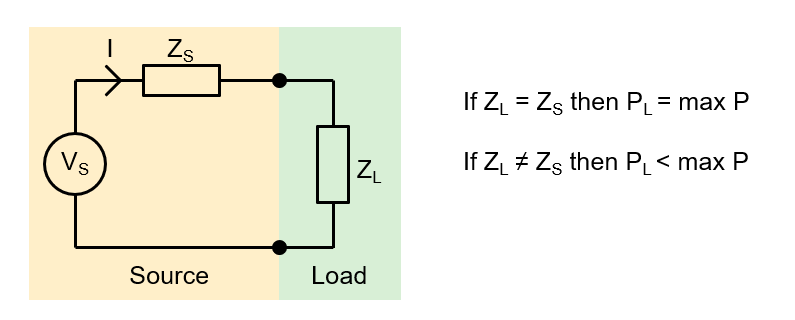

We will explore this concept within the context of a changing load, and use power conversion to maintain an impedance match as seen by the source.

Right click on **impedance_match.slx** and select **Open, **or alternatively run this command by clicking **Run Section** on the tab above,

open_system('impedance_match.slx')

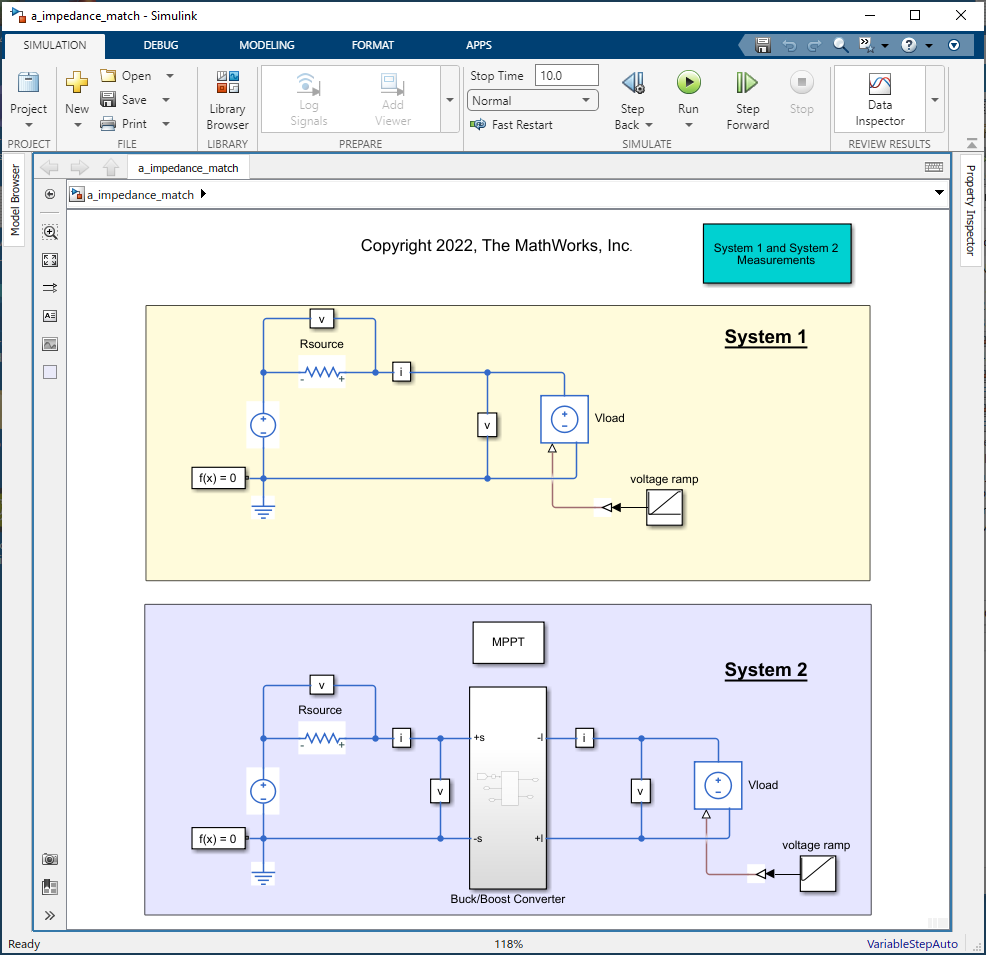

System 1 directly connects the load to the source and changes the load with a voltage ramp. System 2 has a buck/boost power converter between the source and load, and uses a Maximum Power Point Tracking algorithm, based on perturb & observe, to supply the load. The load is subject to a voltage ramp.

Run the model and open the Data Inspector. Select S1.P (power), S1.Vl (load voltage) and S1.Vs (source voltage). Notice that maximum power is delivered when load voltage matches source voltage, in other words when we have an impedance match. Notice that maximum power delivered is 100W at 100V.

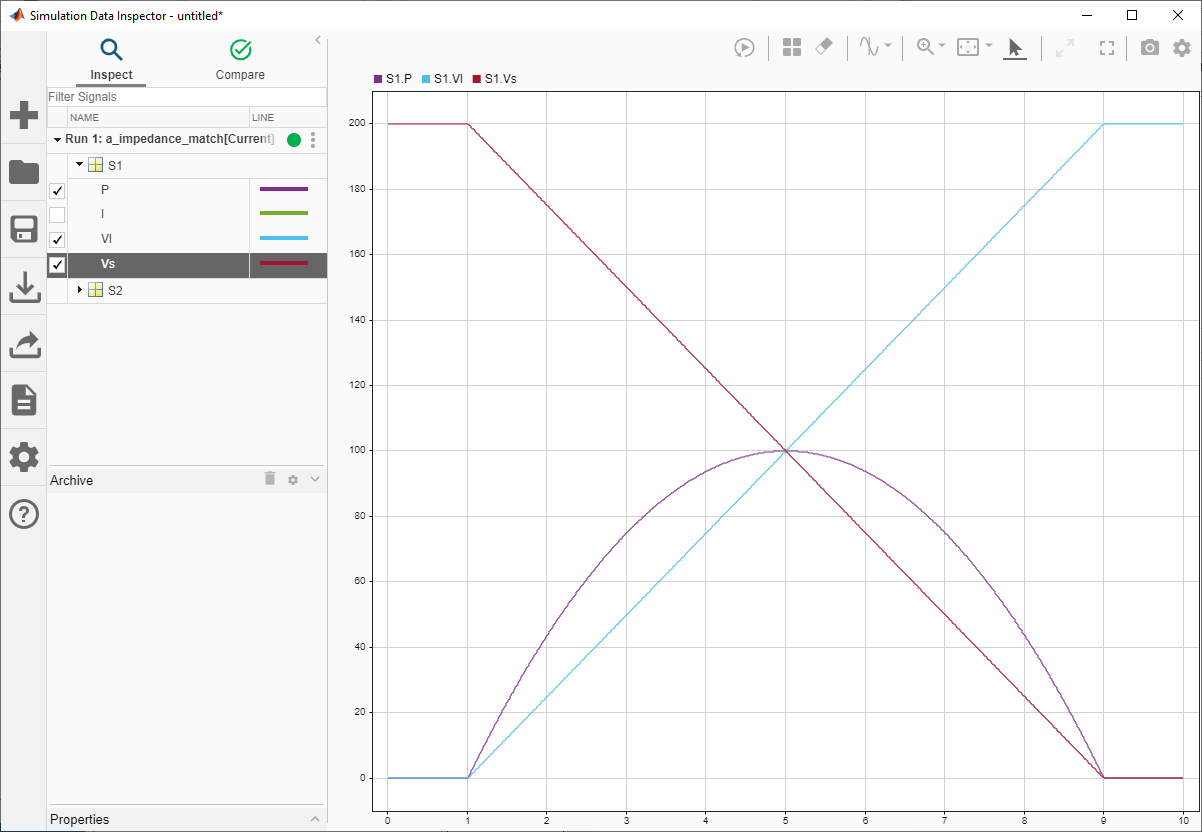

Deselect S1.P (power), S1.Vl (load voltage) and S1.Vs (source voltage) and select S2.P (power), S2.Vl (load voltage) and S2.Vs (source voltage). Notice that even though the load voltage is changing, the source voltage and delivered power is maintained at 100V and 100W respectively. In other words, the MPPT algorithm is presenting a matched impedance to the source, even in the presence of changing load conditions. 

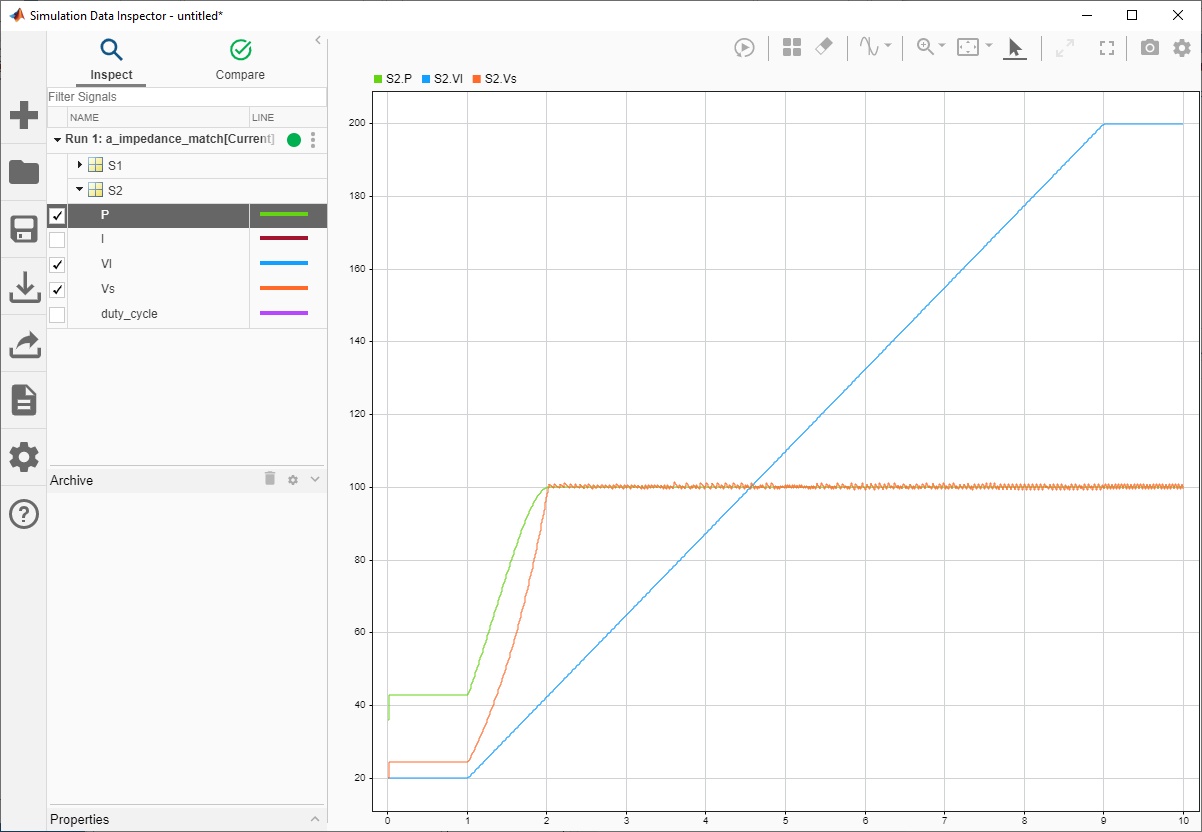

To achieve the impedance match, the MPPT algorithm is changing the duty cycle of the power converter. Deselect S2.P (power), S2.Vl (load voltage) and S2.Vs (source voltage) and select S2. duty_cycle. 

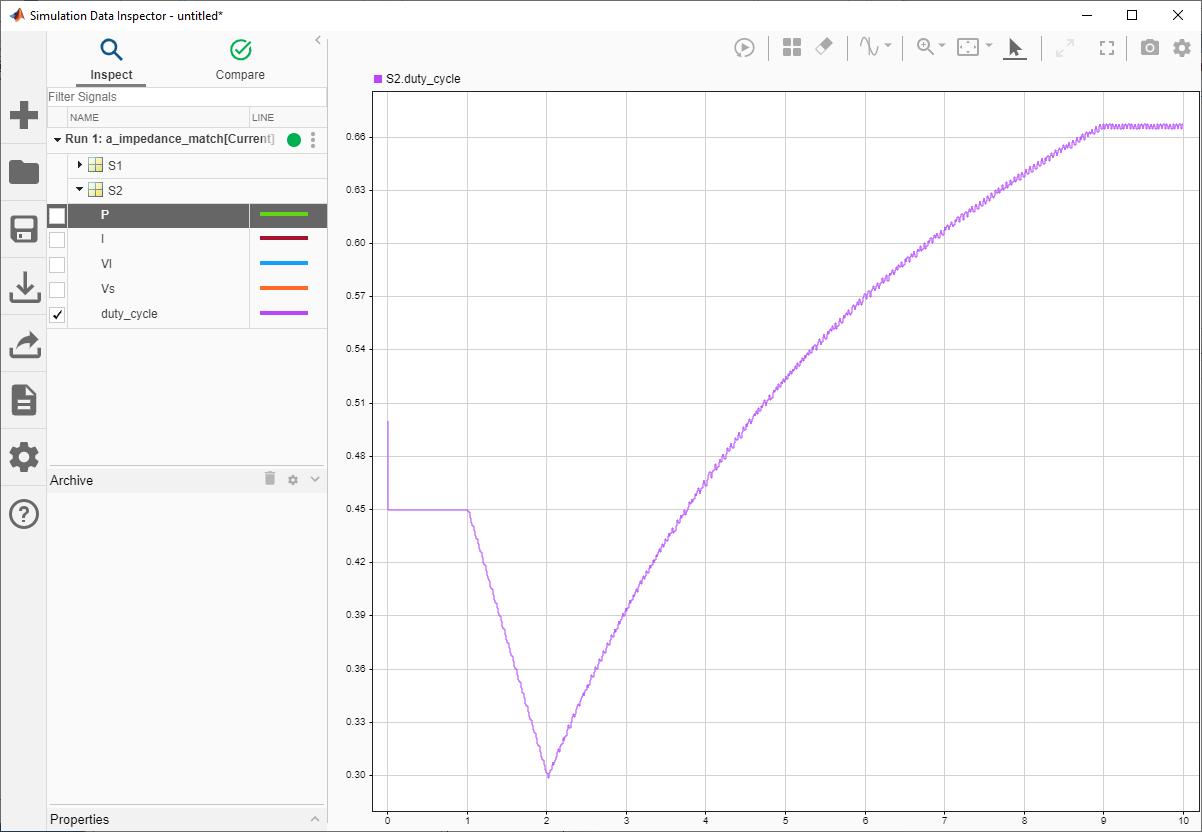

Double-click on the MPPT subsystem to see more detail. The algorithm operates by observing the change in power and adjusting the duty cycle to minimize the change - in other words, find the peak power. 

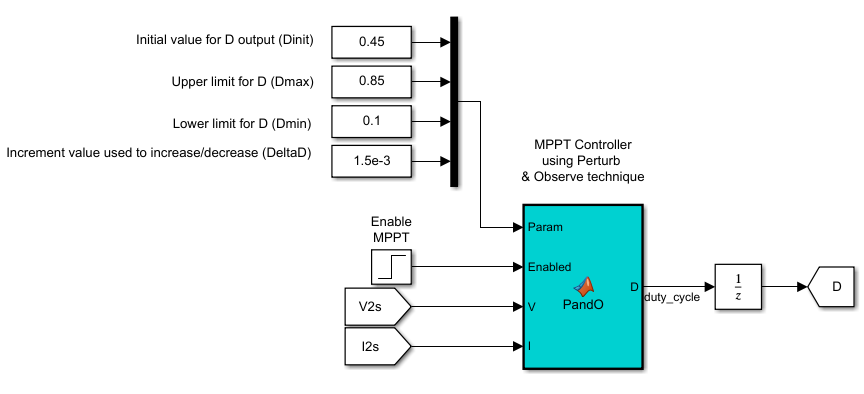

By increasing the **Increment value**, the control will become 'coarser', as larger steps will be taken. Change the increment value to 1e-2 and run the simulation again. Observe the increased noise on the source voltage compared to the previous simulation.